# Test FD solvers accuracy and speed

Tests NIRFAST available sparse linear problems solvers:

- GPU - GPU (CUDA) parallel implementation of the BiCGStab (preconditioned with FSAI)

- CPU - CPU (OpenMP) parallel implementation of the BiCGStab (preconditioned with FSAI)

- MAT - MATLAB BiCGStab implementation (preconditioned with incomplete Cholesky or Cholesky)

- \ - MATLAB backslash, LU decomposition for symmetrical problems

Uses a slab (120x120x50mm) mesh with a coarse element size (~1.85mm^3) to test NIRFAST FD solvers:

- speed

- accuracy against diffusion equation solved for semi-infinite model

- accuracy of BiCGStab iterative solvers against the direct solver '\'

The test mesh is available as ‘slab_stnd’ mesh. But use any slab (semi-infinite-ish) mesh. Homogenous optical properties: mua=0.01mm^-1 (absorption), musp=1mm^-1 (reduced scattering). Solvers tolerances set to the default 1e-12 (see 'solver_options'.

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w')

## generate data with all solvers

mesh = load_mesh('slab_stnd');

Sources integration functions loaded
Detectors integration functions loaded


% set opt. prop.
mesh.mua = ones(size(mesh.mua))*0.01;
mesh.mus = ones(size(mesh.mus))*1;
% set boundary at the slab top only (to match the semi-infinite model as
% close as possible)
top_surface_position = max(mesh.nodes(:,3));
mask_top = (mesh.nodes(:,3) > 0.97*top_surface_position) & (logical(mesh.bndvtx));
% only the top surface is the boundary
mesh.bndvtx(~mask_top) = 0;
% mesh.ksi(~mask_top) = 0;

frequency = 100e6;

% which source we want to observe
source_no = 1;

% GPU
timeStart = tic;
if isCUDA
    [data_GPU, info_GPU] = femdata_FD(mesh,frequency,solver_name_GPU);
    time_execution(1) = toc(timeStart);
else
    warning('No supported GPU found. GPU test skipped.');
    time_execution(1) = NaN;
end

% CPU
timeStart = tic;
[data_CPU, info_CPU] = femdata_FD(mesh,frequency,solver_name_CPU);
time_execution(2) = toc(timeStart);

% MATLAB 'bicgstab'
timeStart = tic;
[data_MAT, info_MAT] = femdata_FD(mesh,frequency,solver_name_matlab_iterative);
time_execution(3) = toc(timeStart);

% backslash
timeStart = tic;
[data_backslash, info_backslash] = femdata_FD(mesh,frequency,solver_name_backslash);
time_execution(4) = toc(timeStart);

## plot mesh

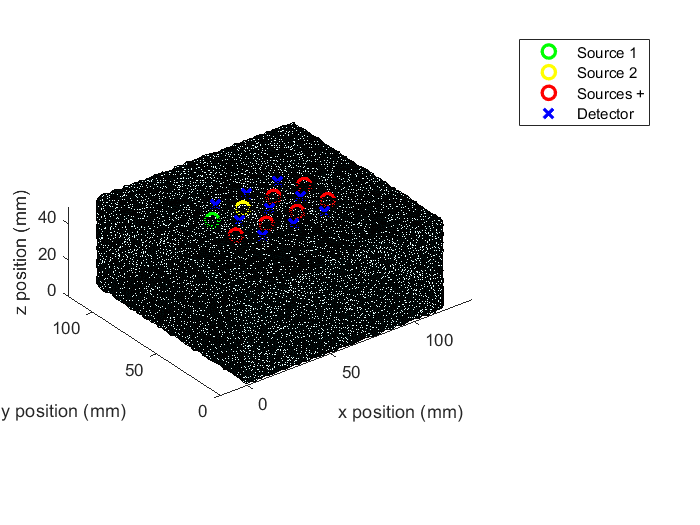

plotmesh_fiducials(mesh)

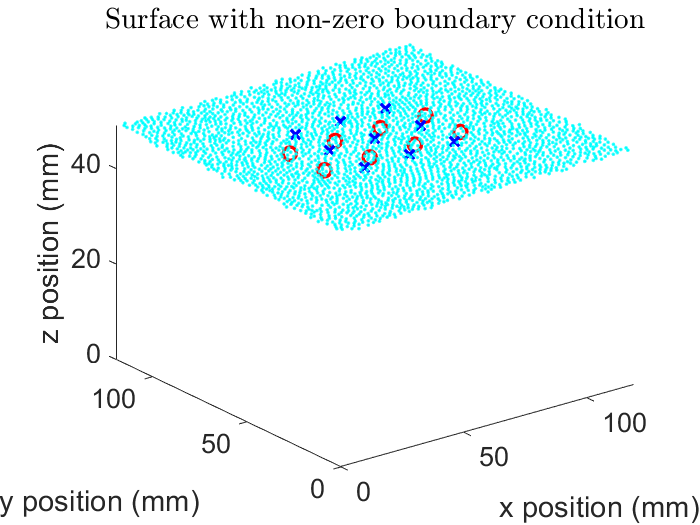


figure('Name',mesh.name)
plot3(mesh.nodes(logical(mesh.bndvtx),1),mesh.nodes(logical(mesh.bndvtx),2),mesh.nodes(logical(mesh.bndvtx),3),'.c')
hold on
plot3(mesh.source.coord(:,1),mesh.source.coord(:,2),mesh.source.coord(:,3),'ro','LineWidth',2,'MarkerSize',8)
plot3(mesh.meas.coord(:,1),mesh.meas.coord(:,2),mesh.meas.coord(:,3),'bx',...
            'LineWidth',2,'MarkerSize',8)
set(gca,'Xlim',[min(mesh.nodes(:,1)) max(mesh.nodes(:,1))],...
    'Ylim',[min(mesh.nodes(:,2)) max(mesh.nodes(:,2))],...
    'Zlim',[min(mesh.nodes(:,3)) max(mesh.nodes(:,3))])
title('Surface with non-zero boundary condition','Interpreter','latex')
view(3);

xlabel('x position (mm)');
ylabel('y position (mm)');
zlabel('z position (mm)');

## plot execution time

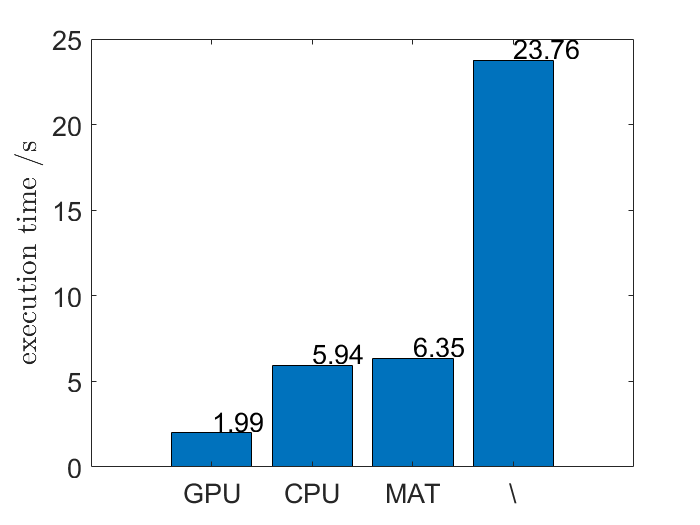

figure('Name',mesh.name)
if isCUDA
    labels = {'GPU','CPU','MAT','\'};
    to_plot = 1:4;
else
    labels = {'CPU','MAT','\'};
    to_plot = 2:4;
end
bar(time_execution(to_plot))
hold on
for ind_exec = 1:length(time_execution)
    text(ind_exec,time_execution(ind_exec)+0.03*max(time_execution),num2str(time_execution(ind_exec),'%4.2f'))
end
hold off
set(gca,'XTickLabel',labels)
ylabel('execution time /s','Interpreter','latex','FontSize',22)

## compare to semi infinite

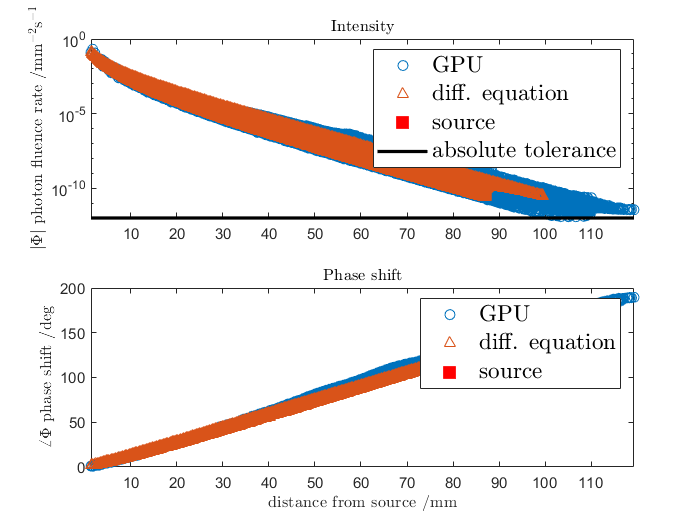

% nodal distances from this source for FEM method
dist = sqrt(sum((mesh.nodes - mesh.source.coord(source_no,:)).^2,2));

% apply semi-infinite diffusion equation
% distance from source in X coordinate
x = mesh.nodes(:,1)-mesh.source.coord(source_no,1);
% distance from surface in Z coordinate
z = abs(mesh.nodes(:,3)-max(mesh.nodes(:,3)));
% mean free path
z0 = 1./mean(mesh.mus);
% nodal distances from this source for semi-infinite method
dist_semi = sqrt((z - z0).^2 + x.^2);
% solve the diffusion equation, use 'robin' boundary condition to match FEM
data_semi = semi_infinite_FD(mean(mesh.mua),mean(mesh.mus),mean(mesh.ri),frequency,x,z,'robin');


figure('Name',mesh.name)
subplot(2,1,1)
if isCUDA
    semilogy(dist,abs(data_GPU.phi(:,source_no)),'o')
else
    semilogy(dist,abs(data_CPU.phi(:,source_no)),'o')
end
hold on
semilogy(dist_semi,abs(data_semi),'^')
semilogy(0,1,'sr','MarkerFaceColor','r','MarkerSize',10)
plot([min(dist) max(dist)], [info_CPU.convergence_tolerance_limit info_CPU.convergence_tolerance_limit],'-k','LineWidth',2)
set(gca,'YScale','log')
% xlim([min(dist) max(dist)])
xlim([0 max(dist)])
title('Intensity','Interpreter','latex','FontSize',22)
ylabel('$|\Phi|$ photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex','FontSize',16)
if isCUDA
    legend({'GPU','diff. equation','source','absolute tolerance'},'Interpreter','latex','FontSize',14)
else
    legend({'CPU','diff. equation','source','absolute tolerance'},'Interpreter','latex','FontSize',14)
end

% get angle
if isCUDA
    ang = angle(data_GPU.phi(:,source_no));
else
    ang = angle(data_CPU.phi(:,source_no));
end
ang(ang<0) = ang(ang<0) + 2*pi;

subplot(2,1,2)
plot(dist,ang*180/pi,'o')
hold on
plot(dist_semi,angle(data_semi)*180/pi,'^')
plot(0,0,'sr','MarkerFaceColor','r','MarkerSize',10)
% xlim([min(dist) max(dist)])
xlim([0 max(dist)])
title('Phase shift','Interpreter','latex','FontSize',22)
xlabel('distance from source /mm','Interpreter','latex','FontSize',22)
ylabel('$\angle\Phi$ phase shift /deg','Interpreter','latex','FontSize',16)
if isCUDA
    legend({'GPU','diff. equation','source'},'Interpreter','latex','FontSize',14)
else
    legend({'CPU','diff. equation','source'},'Interpreter','latex','FontSize',14)
end

## plot accuracy of BiCGStab solvers, per node

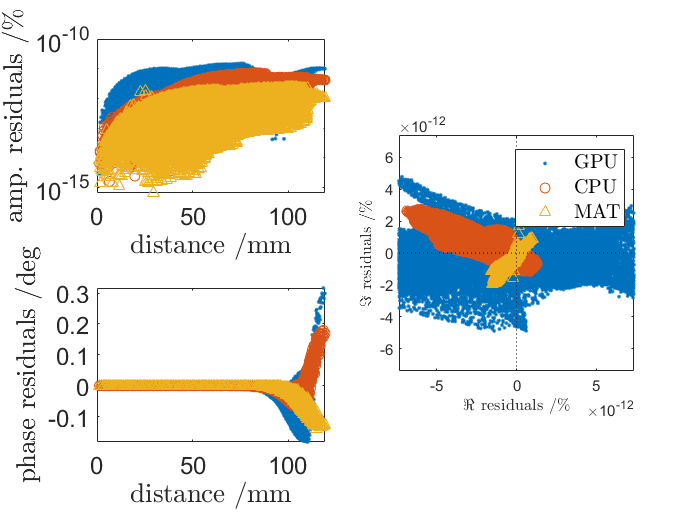

% relate to backslash
if isCUDA
    residuals_GPU = (data_backslash.phi(:,source_no) - data_GPU.phi(:,source_no));
end
residuals_CPU = (data_backslash.phi(:,source_no) - data_CPU.phi(:,source_no));
residuals_MAT = (data_backslash.phi(:,source_no) - data_MAT.phi(:,source_no));

% source power is 1+1j*eps, so the difference in percents is just times 100 the residuals

figure('Name',mesh.name)
subplot(2,2,1)
if isCUDA
    plot(dist,abs(residuals_GPU)*100,'.')
end
hold on
plot(dist,abs(residuals_CPU)*100,'o')
plot(dist,abs(residuals_MAT)*100,'^')
box on
set(gca,'YScale','log')
xlabel('distance /mm','Interpreter','latex','FontSize',22)
ylabel('amp. residuals /\%','Interpreter','latex','FontSize',22)

subplot(2,2,3)
ang1 = angle(data_backslash.phi(:,source_no));
ang1(ang1<0) = ang1(ang1<0) + 2*pi;
if isCUDA
    ang2 = angle(data_GPU.phi(:,source_no));
    ang2(ang2<0) = ang2(ang2<0) + 2*pi;
    plot(dist,(ang2 - ang1)*180/pi,'.')
end
hold on
ang2 = angle(data_CPU.phi(:,source_no));
ang2(ang2<0) = ang2(ang2<0) + 2*pi;
plot(dist,(ang2 - ang1)*180/pi,'o')

ang2 = angle(data_MAT.phi(:,source_no));
ang2(ang2<0) = ang2(ang2<0) + 2*pi;
plot(dist,(ang2 - ang1)*180/pi,'^')
box on
xlabel('distance /mm','Interpreter','latex','FontSize',22)
ylabel('phase residuals /deg','Interpreter','latex','FontSize',22)

subplot(2,2,[2 4])
if isCUDA
    plot(real(residuals_GPU)*100,imag(residuals_GPU)*100,'.')
end
hold on
plot(real(residuals_CPU)*100,imag(residuals_CPU)*100,'o')
plot(real(residuals_MAT)*100,imag(residuals_MAT)*100,'^')
plot([-max(max(abs(residuals_CPU*100))) max(max(abs(residuals_CPU*100)))],[0 0],':k')
plot([0 0],[-max(max(abs(residuals_CPU*100))) max(max(abs(residuals_CPU*100)))],':k')
box on
xlim([-max(max(abs(residuals_CPU*100))) max(max(abs(residuals_CPU*100)))])
ylim([-max(max(abs(residuals_CPU*100))) max(max(abs(residuals_CPU*100)))])
set(gca,'DataAspectRatio',[1 1 1])
xlabel('$\Re$ residuals /\%','Interpreter','latex','FontSize',22)
ylabel('$\Im$ residuals /\%','Interpreter','latex','FontSize',22)
if isCUDA
    legend({'GPU','CPU','MAT'},'Interpreter','latex','FontSize',12)
else
    legend({'CPU','MAT'},'Interpreter','latex','FontSize',12)
end